# Repeat Reunion Part 3A: Session Variance by Interaction Vectors

## Set-up

### Code used for illustration figure

% A1 = [1 1 3 0 0 1 5];
% B1 = [.5 1 3 0 0 1 1];
% B2 = [0 1 5 0 0 0 3];
% A2 = [3 1 0 0 0 4 3];
% mat = [A1' A2' B1' B2'];
% a = squareform(pdist(mat));
% 
% 
% figure
% imagesc(COEFF)
% 
% figure
% plot(SCORE(fem_ind,1), SCORE(fem_ind,2), '.', 'Color', [.5 .5 .5])
% hold
% cag_ind_ex1 = find(rdb_rr.paircode == fem_pairs(cagemates_f(6)) & rdb_rr.exposurenum' < 6);
% str_ind_ex1 = find(rdb_rr.paircode == fem_pairs(ostrangers_f(6)) & rdb_rr.exposurenum' < 6);
% p1 = plot(SCORE(cag_ind_ex1,1), SCORE(cag_ind_ex1,2), 'k.', 'MarkerSize', 20)
% p2 = plot(SCORE(str_ind_ex1,1), SCORE(str_ind_ex1,2), 'r.', 'MarkerSize', 20)
% box off



## Set up variables 

For the dyad analysis

  % we will use a combination of the total interaction and the relationship

  % between interactions as our input. 

  
colorcodes_f = [.75 0 0 ; .4 0 0 ; 1 .35 .35];
colorcodes_m = [0 0 .75 ; 0 0 .4 ; .35 .35 1];


  %if don't yet have a relationship between interactions, here we go:
  %[be_xcorr, xaxis, codes] = Behav_Xcorr(rdb_rr.be_start_end, rdb_rr.be_identcode, betypes);
%   mxc(:,1,:) = nanmean(be_xcorr(:,12:21,:),2).^(1/3);
%   mxc(:,2,:) = nanmean(be_xcorr(:,22:31,:),2).^(1/3);
%   mxc = [squeeze(mxc(:,1,:)) ; squeeze(mxc(:,2,:))]';
  
  
  %we will combine this with the following:
  % sumbehavID2
  

%  sMXC = [sumbehavID2 mxc];
  labels_pair = rdb_rr.paircode;
  exp_pair = rdb_rr.exposurenum;
  
  indfemOneFive_f = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum < 2), fem_ind);
  indfemOneFive_cag_f = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 0), fem_ind);
  indfemOneFive_str_f = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 1), fem_ind);
  
  indmalOneFive_m = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum < 2), mal_ind);
  indmalOneFive_cag_m = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 0), mal_ind);
  indmalOneFive_str_m = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 1), mal_ind);
  
  u_p1_f = unique(labels_pair(indfemOneFive_cag_f));
  u_p2_f = unique(labels_pair(indfemOneFive_str_f));
  u_p_f = [u_p1_f ; u_p2_f];
  
  lp_f = length(u_p1_f);
  
  u_p1_m = unique(labels_pair(indmalOneFive_cag_m));
  u_p2_m = unique(labels_pair(indmalOneFive_str_m));
  u_p_m = [u_p1_m ; u_p2_m];
  
  lp_m = length(u_p1_m);
  


## Dyad distances

### Create the distance matrix using dyad with/IDs

warning('off', 'all');

%distmet = 'mahalanobis';
distmet = 'cosine';
%distmet = 'euclidean';
Distmat_f = IVdist_sess(sumbehavID2.^(1/3), indfemOneFive_f, u_p_f, labels_pair, distmet);
Distmat_m = IVdist_sess(sumbehavID2.^(1/3), indmalOneFive_m, u_p_m, labels_pair, distmet);


#### Address the main hypothesis: how do within-dyad distances differ in stranger and cagemates between the two sexes?

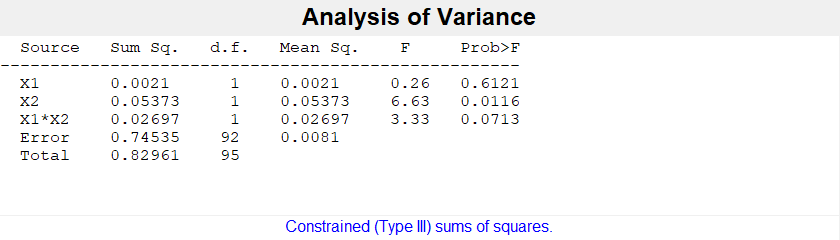

windistmat_f = diag(Distmat_f);
btwdistmat_f = Distmat_f;
btwdistmat_f(find(eye(length(Distmat_f)))) = nan;

windistmat_m = diag(Distmat_m);
btwdistmat_m = Distmat_m;
btwdistmat_m(find(eye(length(Distmat_m)))) = nan;


%anova to test for different means between groups
win_cag_f = windistmat_f(1:lp_f);
btw_cag_f = reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]);
win_str_f = windistmat_f(lp_f+1:2*lp_f); 
btw_str_f = reshape(btwdistmat_f(lp_f+1:2*lp_f,lp_f+1:2*lp_f), 1,[]);

win_cag_m = windistmat_m(1:lp_m);
btw_cag_m = reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]);
win_str_m = windistmat_m(lp_m+1:2*lp_m); 
btw_str_m = reshape(btwdistmat_m(lp_m+1:2*lp_m,lp_m+1:2*lp_m), 1,[]);


anovacell{1} = [win_cag_f ; win_str_f ; win_cag_m ; win_str_m ];
anovacell{2} = [ones(length(win_cag_f),1) ;  2*ones(length(win_str_f),1); ...
     ones(length(win_cag_m),1) ; 2*ones(length(win_str_m),1)];
%anovacell{3} = [ones(length(win_cag_f),1) ; 2*ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1);...
 %   ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
anovacell{3} = [ ones(length(win_cag_f),1) ;  ones(length(win_str_f),1);...
     2*ones(length(win_cag_m),1) ; 2*ones(length(win_str_m),1)];

[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

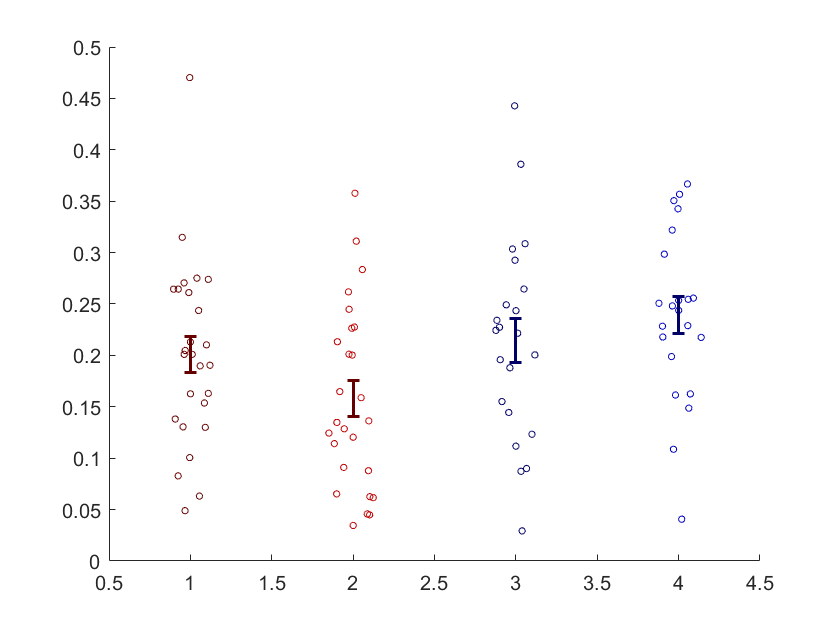



  figure
  hold on
%  e1 = errorbar([1 2], [nanmean(windistmat(1:lp)) nanmean(reshape(btwdistmat(1:lp, 1:lp), 1,[]))], ...
%      [nanstd(windistmat(1:lp)) nanstd(reshape(btwdistmat(1:lp, 1:lp), 1,[]))]./[sqrt(lp-1) sqrt((lp^2-lp)/2)], 'LineStyle', 'none', 'LineWidth', 1.5);
%  
%  e2 = errorbar([3 4], [nanmean(windistmat(lp+1:2*lp)) nanmean(reshape(btwdistmat(lp+1:2*lp, lp+1:2*lp), 1,[]))], ...
%      [nanstd(windistmat(lp+1:2*lp)) nanstd(reshape(btwdistmat(lp+1:2*lp, lp+1:2*lp), 1,[]))]./[sqrt(lp-1) sqrt((lp^2-lp)/2)], 'LineStyle', 'none', 'LineWidth', 1.5);
%  

colorcodes_fem = colorcodes_f;
colorcodes_mal = colorcodes_m;

clear s
 s{1} = swarmchart(ones(lp_f,1), windistmat_f(1:lp_f), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
 errorbar(1, mean(windistmat_f(1:lp_f)), std(windistmat_f(1:lp_f))/sqrt(lp_f-1), 'Color', colorcodes_fem(2,:), 'LineWidth', 1.5);
 
 %s{2} = swarmchart(2*ones(lp_f*lp_f,1), reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
 
 s{2} = swarmchart(2*ones(lp_f,1), windistmat_f(lp_f+1:2*lp_f), 10, 'MarkerEdgeColor', colorcodes_fem(1,:)) ;
 errorbar(2, mean(windistmat_f(lp_f+1:2*lp_f)), std(windistmat_f(lp_f+1:2*lp_f))/sqrt(lp_f-1), 'Color', colorcodes_fem(2,:), 'LineWidth', 1.5);
 %s{4} = swarmchart(4*ones(lp_f*lp_f,1), reshape(btwdistmat_f(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(1,:));
 
 
 x_shift = 2;
 s{3} = swarmchart(x_shift + ones(lp_m,1), windistmat_m(1:lp_m), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
 errorbar(3, mean(windistmat_m(1:lp_m)), std(windistmat_m(1:lp_m))/sqrt(lp_m-1), 'Color', colorcodes_mal(2,:), 'LineWidth', 1.5);
 %s{6} = swarmchart(x_shift + 2*ones(lp_m*lp_m,1), reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
 s{4} = swarmchart(x_shift + 2*ones(lp_m,1), windistmat_m(lp_m+1:2*lp_m), 10, 'MarkerEdgeColor', colorcodes_mal(1,:)) ;
  errorbar(4, mean(windistmat_m(lp_m+1:2*lp_m)), std(windistmat_m(lp_m+1:2*lp_m))/sqrt(lp_m-1), 'Color', colorcodes_mal(2,:), 'LineWidth', 1.5);
 %s{8} = swarmchart(x_shift +4*ones(lp_m*lp_m,1), reshape(btwdistmat_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(1,:));
 
 
 
 
 for i = 1:4
     set(s{i}, 'XJitterWidth', .3);
 end
  box off

Figure for talks

 figure
 bar(mean(windistmat_f(1:lp_f)), 'FaceColor', [.6 .6 .6], 'LineWidth', 1.5);
 hold

Current plot held


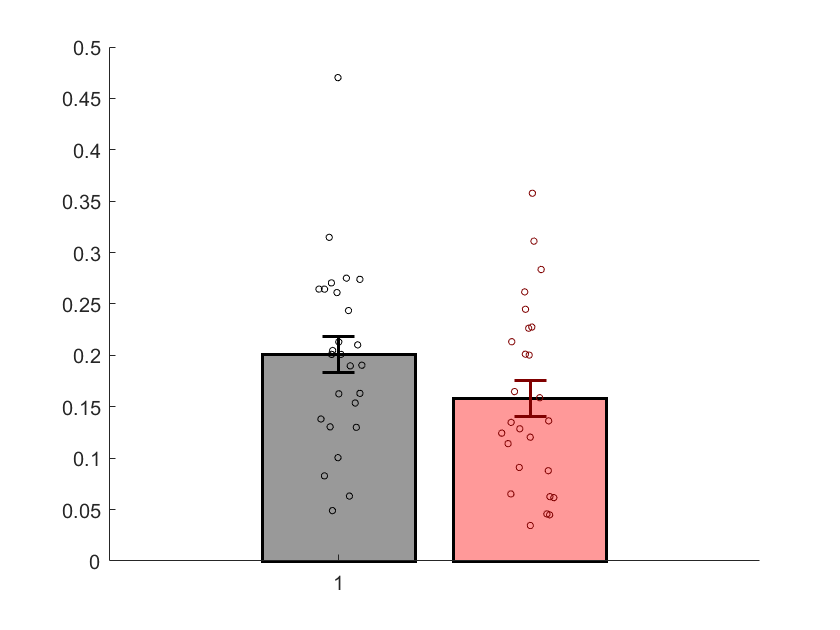

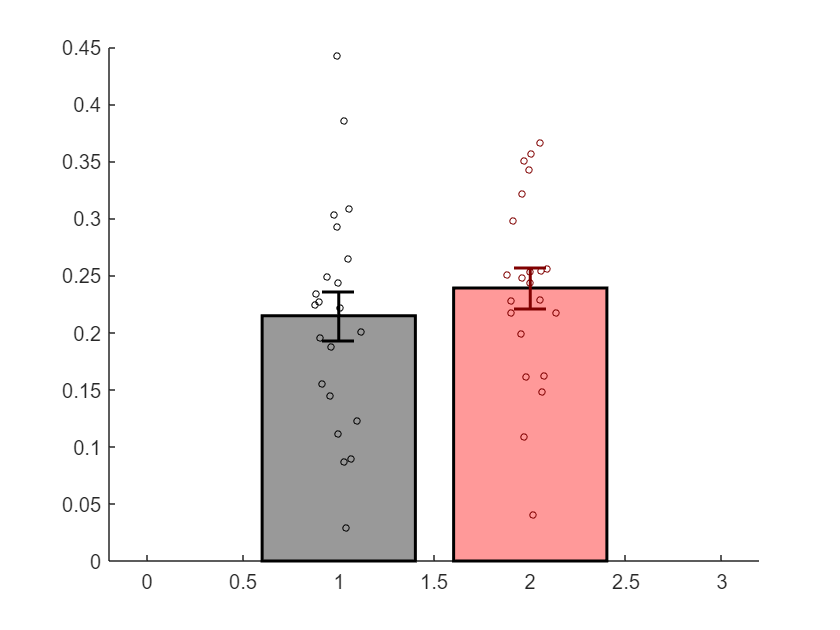

  e1 = errorbar(1, mean(windistmat_f(1:lp_f)), std(windistmat_f(1:lp_f))/sqrt(lp_f-1), 'Color', [0 0 0], 'LineWidth', 1.5);
  s{1} = swarmchart(ones(lp_f,1), windistmat_f(1:lp_f), 10, 'MarkerEdgeColor', [0 0 0]);
  set(e1, 'CapSize', 16)
%  set(s{1}, 'MarkerEdgeColor', )
  
  
   bar(2, mean(windistmat_f(lp_f+1:2*lp_f)), 'FaceColor', [1 .6 .6], 'LineWidth', 1.5);
 e2 = errorbar(2, mean(windistmat_f(lp_f+1:2*lp_f)), std(windistmat_f(lp_f+1:2*lp_f))/sqrt(lp_f-1), 'Color',  [.5 0 0], 'LineWidth', 1.5);
   s{2} = swarmchart(2*ones(lp_f,1), windistmat_f(lp_f+1:2*lp_f), 10, 'MarkerEdgeColor', [.5 0 0]) ;
     set(e2, 'CapSize', 16)
   box off
   
   figure
   hold on
 x_shift = 2;
 bar(mean(windistmat_m(1:lp_m)), 'FaceColor', [.6 .6 .6], 'LineWidth', 1.5)
 e3 = errorbar(1, mean(windistmat_m(1:lp_m)), std(windistmat_m(1:lp_m))/sqrt(lp_m-1), 'Color', [0 0 0], 'LineWidth', 1.5);
 s{3} = swarmchart(ones(lp_m,1), windistmat_m(1:lp_m), 10, 'MarkerEdgeColor', [0 0 0]); 
   set(e3, 'CapSize', 16)
 
 bar(2, mean(windistmat_m(lp_m+1:2*lp_m)), 'FaceColor', [1 .6 .6], 'LineWidth', 1.5)
 e4 = errorbar(2, mean(windistmat_m(lp_m+1:2*lp_m)), std(windistmat_m(lp_m+1:2*lp_m))/sqrt(lp_m-1), 'Color', [.5 0 0], 'LineWidth', 1.5);
 s{4} = swarmchart(2*ones(lp_m,1), windistmat_m(lp_m+1:2*lp_m), 10, 'MarkerEdgeColor', [.5 0 0]) ;
   set(e4, 'CapSize', 16)
   
 %s{6} = swarmchart(x_shift + 2*ones(lp_m*lp_m,1), reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 


 %s{8} = swarmchart(x_shift +4*ones(lp_m*lp_m,1), reshape(btwdistmat_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(1,:));
 
 
 
 
 for i = 1:4
     set(s{i}, 'XJitterWidth', .3);
 end

 [a bm] = ttest2(windistmat_m(1:lp_m), windistmat_m(lp_m+1:2*lp_m))

a = 0

bm = 0.3818

 
  [a bf] = ttest2(windistmat_f(1:lp_f), windistmat_f(lp_f+1:2*lp_f))

a = 0

bf = 0.0881

### Add complexity: include between-dyad distances (currently unused)

### Create figure of within versus between dyad distances

windistmat_f = diag(Distmat_f);
btwdistmat_f = Distmat_f;
btwdistmat_f(find(eye(length(Distmat_f)))) = nan;

windistmat_m = diag(Distmat_m);
btwdistmat_m = Distmat_m;
btwdistmat_m(find(eye(length(Distmat_m)))) = nan;



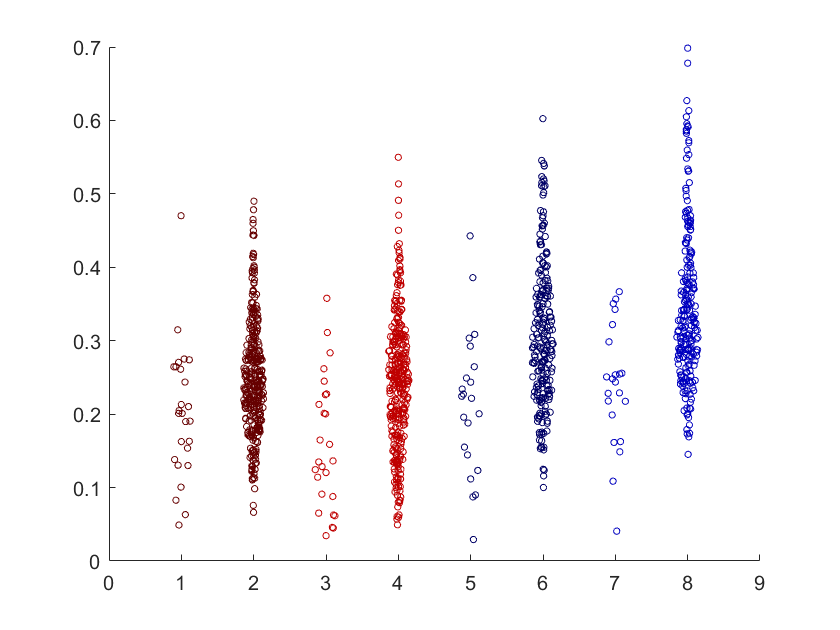


  figure
  hold on
%  e1 = errorbar([1 2], [nanmean(windistmat(1:lp)) nanmean(reshape(btwdistmat(1:lp, 1:lp), 1,[]))], ...
%      [nanstd(windistmat(1:lp)) nanstd(reshape(btwdistmat(1:lp, 1:lp), 1,[]))]./[sqrt(lp-1) sqrt((lp^2-lp)/2)], 'LineStyle', 'none', 'LineWidth', 1.5);
%  
%  e2 = errorbar([3 4], [nanmean(windistmat(lp+1:2*lp)) nanmean(reshape(btwdistmat(lp+1:2*lp, lp+1:2*lp), 1,[]))], ...
%      [nanstd(windistmat(lp+1:2*lp)) nanstd(reshape(btwdistmat(lp+1:2*lp, lp+1:2*lp), 1,[]))]./[sqrt(lp-1) sqrt((lp^2-lp)/2)], 'LineStyle', 'none', 'LineWidth', 1.5);
%  

clear s
 s{1} = swarmchart(ones(lp_f,1), windistmat_f(1:lp_f), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
 
 s{2} = swarmchart(2*ones(lp_f*lp_f,1), reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
 
 s{3} = swarmchart(3*ones(lp_f,1), windistmat_f(lp_f+1:2*lp_f), 10, 'MarkerEdgeColor', colorcodes_fem(1,:)) ;
 s{4} = swarmchart(4*ones(lp_f*lp_f,1), reshape(btwdistmat_f(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(1,:));
 
 
 x_shift = 4;
 s{5} = swarmchart(x_shift + ones(lp_m,1), windistmat_m(1:lp_m), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
 s{6} = swarmchart(x_shift + 2*ones(lp_m*lp_m,1), reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
 s{7} = swarmchart(x_shift + 3*ones(lp_m,1), windistmat_m(lp_m+1:2*lp_m), 10, 'MarkerEdgeColor', colorcodes_mal(1,:)) ;
 s{8} = swarmchart(x_shift +4*ones(lp_m*lp_m,1), reshape(btwdistmat_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(1,:));
 
 
 
 
 for i = 1:8
     set(s{i}, 'XJitterWidth', .3);
 end
  box off

wVb_dist_f = windistmat_f./nanmean(btwdistmat_f,2);
[nanmean(wVb_dist_f(1:lp_f)) nanmean(wVb_dist_f((lp_f+1):end))]

ans =     0.7413    0.6089


  
[~, pwvbn, ~, tpwvbn] = ttest2(wVb_dist_f(1:lp_f), wVb_dist_f((lp_f+1):end)) 

pwvbn = 0.0628

tpwvbn = struct with fields:
    tstat: 1.9038
       df: 49
       sd: 0.2483


### Statistical comparison of distances (including "between")

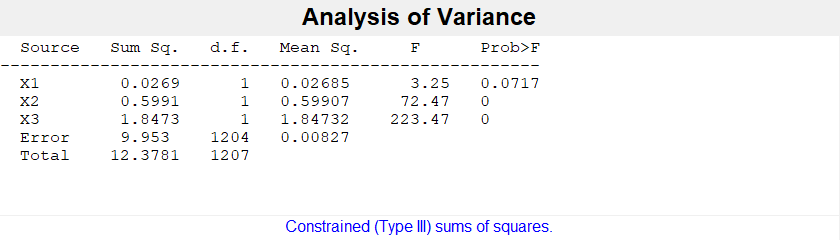

%anova to test for different means between groups
win_cag_f = windistmat_f(1:lp_f);
btw_cag_f = reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]);
win_str_f = windistmat_f(lp_f+1:2*lp_f); 
btw_str_f = reshape(btwdistmat_f(lp_f+1:2*lp_f,lp_f+1:2*lp_f), 1,[]);

win_cag_m = windistmat_m(1:lp_m);
btw_cag_m = reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]);
win_str_m = windistmat_m(lp_m+1:2*lp_m); 
btw_str_m = reshape(btwdistmat_m(lp_m+1:2*lp_m,lp_m+1:2*lp_m), 1,[]);



anovacell{1} = [win_cag_f ; btw_cag_f' ; win_str_f ; btw_str_f' ; win_cag_m ; btw_cag_m' ; win_str_m ; btw_str_m'];
anovacell{2} = [ones(length(win_cag_f),1) ; ones(length(btw_cag_f),1) ; 2*ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1); ...
    ones(length(win_cag_m),1) ; ones(length(btw_cag_m),1) ; 2*ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
anovacell{3} = [ones(length(win_cag_f),1) ; 2*ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1);...
    ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
anovacell{4} = [ones(length(win_cag_f),1) ; ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; ones(length(btw_str_f),1);...
    2*ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; 2*ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];

% X1 is cag vs. str
% X2 is within vs between
% X3 is female vs. male

[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:4));

### Control to assess within vs. between difference: scramble interactions

This takes about 15 min? Works but currently not included, for simiplicity

% scram_sb = sumbehavID2;
% 
% scramFs = nan(1000,3);
% tic
% for j = 1:1000 %loop across 1000 iterations
%     fprintf('%d ',j);
%     if rem(j,50) == 0
%         toc
%         tic
%     end
%     for i = 1:size(scram_sb,1)
%         scram_sb(i,:) = sumbehavID2(i,randperm(size(sumbehavID2,2)));    
%     end
% 
%     
% %Distmat = IVdist_sess(scram_sb.^(1/3), indfemOneFive, u_p, labels_pair, distmet);
%   
%   windistmat = diag(Distmat);
% btwdistmat = Distmat;
% btwdistmat(find(eye(length(Distmat)))) = nan;
% 
% lp = length(u_p1);
% 
% 
%   win_cag = windistmat(1:lp);
% btw_cag = reshape(btwdistmat(1:lp, 1:lp), 1,[]);
% win_str = windistmat(lp+1:2*lp); 
% btw_str = reshape(btwdistmat(lp+1:2*lp,lp+1:2*lp), 1,[]);
% 
% anovacell{1} = [win_cag ; btw_cag' ; win_str ; btw_str'];
% anovacell{2} = [ones(length(win_cag),1) ; ones(length(btw_cag),1) ; 2*ones(length(win_str),1) ; 2*ones(length(btw_str),1)];
% anovacell{3} = [ones(length(win_cag),1) ; 2*ones(length(btw_cag),1) ; ones(length(win_str),1) ; 2*ones(length(btw_str),1)];
% 
% strev = '[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), ''model'', ''interaction'')';
% 
% evalc(strev);
%  scramFsEUC(j,1) = T{2,6};
%  scramFsEUC(j,2) = T{3,6};
%  scramFsEUC(j,3) = T{4,6};
% 
% end

%sscramFs = sort(scramFs); %to assess where the F-stat of the original model lies in relation to the control datasets


### Control to assess within vs. between difference: scramble labels

This takes about 15 min?


% scramLs = nan(1000,3);
% tic
% for j = 1:1000 %loop across 1000 iterations
%     fprintf('%d ',j);
%     if rem(j,50) == 0
%         toc
%         tic
%     end
%     labels_pairs_scram = labels_pair;
%     labels_pairs_scram(indfemOneFive) = labels_pair(indfemOneFive(randperm(length(indfemOneFive))));
% 
%     Distmat = IVdist_sess(sumbehavID2.^(1/3), indfemOneFive, u_p, labels_pairs_scram, distmet);
%   
%     windistmat = diag(Distmat);
%     btwdistmat = Distmat;
%     btwdistmat(find(eye(length(Distmat)))) = nan;
% 
%     lp = length(u_p1);
% 
% 
%     win_cag = windistmat(1:lp);
%     btw_cag = reshape(btwdistmat(1:lp, 1:lp), 1,[]);
%     win_str = windistmat(lp+1:2*lp); 
%     btw_str = reshape(btwdistmat(lp+1:2*lp,lp+1:2*lp), 1,[]);
% 
%     anovacell{1} = [win_cag ; btw_cag' ; win_str ; btw_str'];
%     anovacell{2} = [ones(length(win_cag),1) ; ones(length(btw_cag),1) ; 2*ones(length(win_str),1) ; 2*ones(length(btw_str),1)];
%     anovacell{3} = [ones(length(win_cag),1) ; 2*ones(length(btw_cag),1) ; ones(length(win_str),1) ; 2*ones(length(btw_str),1)];
%     
%     strev = '[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), ''model'', ''interaction'')';
% 
%     evalc(strev);
%      scramLsEUC(j,1) = T{2,6};
%     scramLsEUC(j,2) = T{3,6};
%     scramLsEUC(j,3) = T{4,6};
% 
% end
% 
% sscramLsEUC = sort(scramLsEUC); %to assess where the F-stat of the original model lies in relation to the control datasets


### Check distances after removing individual interaction types from the interaction vector

Removing a behavior: Cosine distance

  
warning('off', 'all');
h = figure

h =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


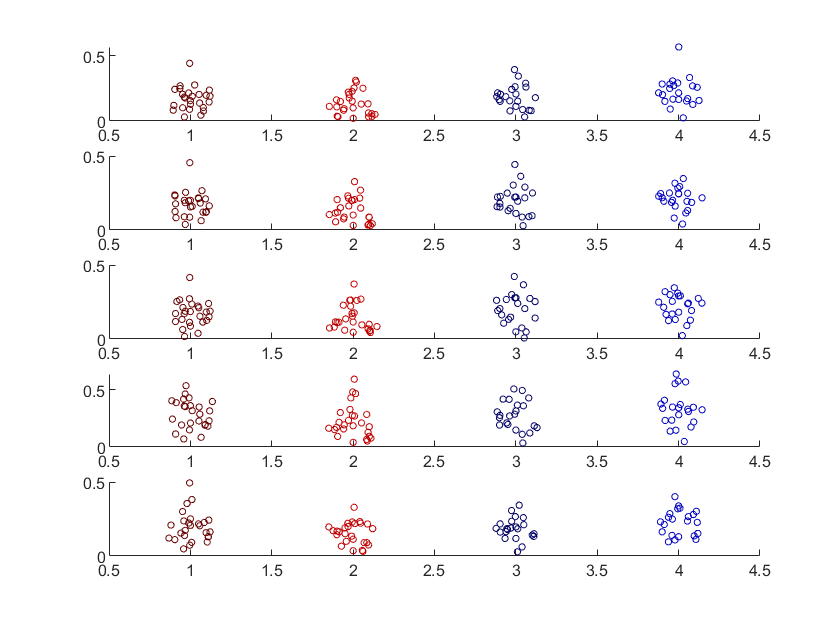

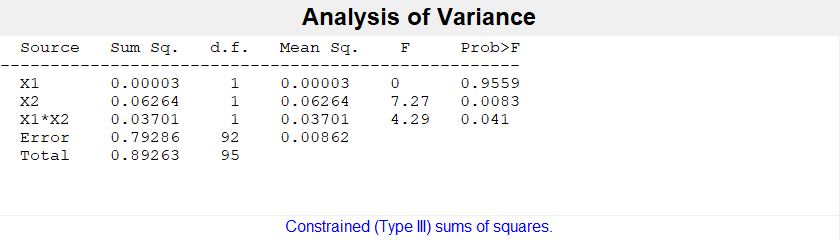

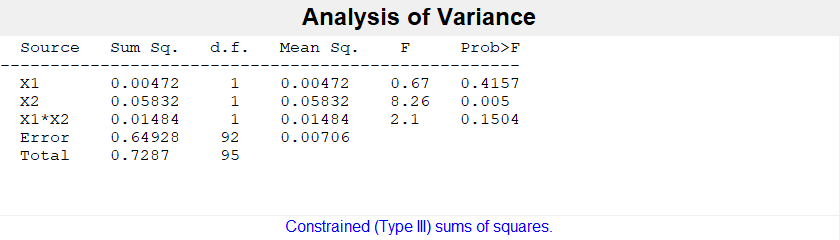

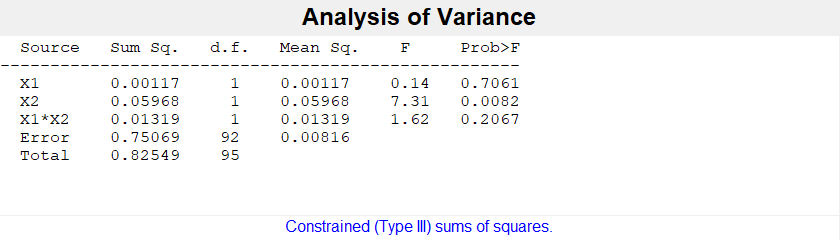

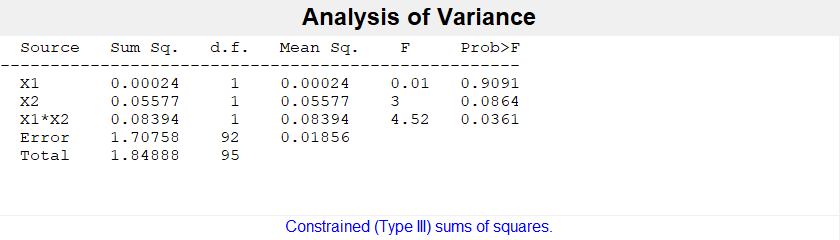

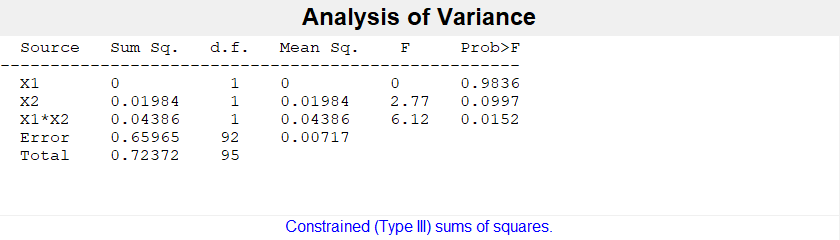


  T_IVR = cell(5,1);
  for k = 1:5
    switch k
        case 1
            newsumbehav = sumbehavID2(:, [2:4 6:end]);
        case 2
            newsumbehav = sumbehavID2(:, [1 3:5 7:end]);
        case 3
            newsumbehav = sumbehavID2(:, [1 2 4:6 8:end]);
        case 4
            newsumbehav = sumbehavID2(:,1:8);
        case 5
            newsumbehav = sumbehavID2(:, [1:3 5:7 9]);
    end
    
    Distmat_f = IVdist_sess(newsumbehav.^(1/3), indfemOneFive_f, u_p_f, labels_pair, 'cosine');
    Distmat_m = IVdist_sess(newsumbehav.^(1/3), indmalOneFive_m, u_p_m, labels_pair, 'cosine');
    
    windistmat_f = diag(Distmat_f);
    btwdistmat_f = Distmat_f;
    btwdistmat_f(find(eye(length(Distmat_f)))) = nan;

    windistmat_m = diag(Distmat_m);
    btwdistmat_m = Distmat_m;
    btwdistmat_m(find(eye(length(Distmat_m)))) = nan;
    
    lp_f = length(u_p1_f);
    lp_m = length(u_p1_m);

    win_cag_f = windistmat_f(1:lp_f);
    btw_cag_f = reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]);
    win_str_f = windistmat_f(lp_f+1:2*lp_f); 
    btw_str_f = reshape(btwdistmat_f(lp_f+1:2*lp_f,lp_f+1:2*lp_f), 1,[]);
    
    win_cag_m = windistmat_m(1:lp_m);
    btw_cag_m = reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]);
    win_str_m = windistmat_m(lp_m+1:2*lp_m); 
    btw_str_m = reshape(btwdistmat_m(lp_m+1:2*lp_m,lp_m+1:2*lp_m), 1,[]);
    

% anovacell{1} = [win_cag_f ; btw_cag_f' ; win_str_f ; btw_str_f' ; win_cag_m ; btw_cag_m' ; win_str_m ; btw_str_m'];
% anovacell{2} = [ones(length(win_cag_f),1) ; ones(length(btw_cag_f),1) ; 2*ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1); ...
%     ones(length(win_cag_m),1) ; ones(length(btw_cag_m),1) ; 2*ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
% anovacell{3} = [ones(length(win_cag_f),1) ; 2*ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1);...
%     ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
% anovacell{4} = [ones(length(win_cag_f),1) ; ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; ones(length(btw_str_f),1);...
%     2*ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; 2*ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
    
anovacell{1} = [win_cag_f ; win_str_f ; win_cag_m  ; win_str_m];
anovacell{2} = [ones(length(win_cag_f),1) ;  2*ones(length(win_str_f),1); ...
     ones(length(win_cag_m),1) ; 2*ones(length(win_str_m),1)];
%anovacell{3} = [ones(length(win_cag_f),1) ; 2*ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1);...
 %   ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
anovacell{3} = [ ones(length(win_cag_f),1) ;  ones(length(win_str_f),1);...
     2*ones(length(win_cag_m),1) ; 2*ones(length(win_str_m),1)];

[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');


    
    T_IVR{k} = T;
    
%     [~, pv2B(k)] = vartest2(btw_cag, btw_str);
%     s2B(k,:) = [nanstd(btw_cag) nanstd(btw_str)];
% %f-test of uneven variances: within
%     [~, pv2W(k)] = vartest2(win_cag, win_str);
%     
%     [~, pt2B(k)] = ttest2(btw_cag, btw_str);
    
   figure(h)
    subplot(5,1,k)
    hold on
    clear s
 s{1} = swarmchart(ones(lp_f,1), windistmat_f(1:lp_f), 10, 'MarkerEdgeColor', colorcodes_f(2,:));
 
% s{2} = swarmchart(2*ones(lp_f*lp_f,1), reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
 
 s{2} = swarmchart(2*ones(lp_f,1), windistmat_f(lp_f+1:2*lp_f), 10, 'MarkerEdgeColor', colorcodes_f(1,:)) ;
% s{4} = swarmchart(4*ones(lp_f*lp_f,1), reshape(btwdistmat_f(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(1,:));
 
 
 x_shift = 2;
 s{3} = swarmchart(x_shift + ones(lp_m,1), windistmat_m(1:lp_m), 10, 'MarkerEdgeColor', colorcodes_m(2,:)); 
% s{6} = swarmchart(x_shift + 2*ones(lp_m*lp_m,1), reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
 s{4} = swarmchart(x_shift + 2*ones(lp_m,1), windistmat_m(lp_m+1:2*lp_m), 10, 'MarkerEdgeColor', colorcodes_m(1,:)) ;
% s{8} = swarmchart(x_shift +4*ones(lp_m*lp_m,1), reshape(btwdistmat_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(1,:));
 
 
     for i = 1:4
        set(s{i}, 'XJitterWidth', .3);
     end
    
  end

Euclidean with between (needs editing, should stick with cosine at this point)

The one that drops the interaction term the most is agonistic. Without agonistic, a lot of the diversity decreases. Need to cross-check this with the SVM methods

  
% 
%   T_IVR = cell(5,1);
%   for k = 1:5
%     switch k
%         case 1
%             newsumbehav = sumbehavID2(:, [2:4 6:end]);
%         case 2
%             newsumbehav = sumbehavID2(:, [1 2:5 7:end]);
%         case 3
%             newsumbehav = sumbehavID2(:, [1 2:5 7:end]);
%         case 4
%             newsumbehav = sumbehavID2(:,1:8);
%         case 5
%             newsumbehav = sumbehavID2(:, [1:3 5:7 9]);
%     end
%     
%     Distmat_f = IVdist_sess(newsumbehav.^(1/3), indfemOneFive_f, u_p_f, labels_pair, 'euclidean');
%     Distmat_m = IVdist_sess(newsumbehav.^(1/3), indmalOneFive_m, u_p_m, labels_pair, 'euclidean');
%     
%     windistmat_f = diag(Distmat_f);
%     btwdistmat_f = Distmat_f;
%     btwdistmat_f(find(eye(length(Distmat_f)))) = nan;
% 
%     windistmat_m = diag(Distmat_m);
%     btwdistmat_m = Distmat_m;
%     btwdistmat_m(find(eye(length(Distmat_m)))) = nan;
%     
%     lp_f = length(u_p1_f);
%     lp_m = length(u_p1_m);
% 
%     win_cag_f = windistmat_f(1:lp_f);
%     btw_cag_f = reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]);
%     win_str_f = windistmat_f(lp_f+1:2*lp_f); 
%     btw_str_f = reshape(btwdistmat_f(lp_f+1:2*lp_f,lp_f+1:2*lp_f), 1,[]);
%     
%     win_cag_m = windistmat_m(1:lp_m);
%     btw_cag_m = reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]);
%     win_str_m = windistmat_m(lp_m+1:2*lp_m); 
%     btw_str_m = reshape(btwdistmat_m(lp_m+1:2*lp_m,lp_m+1:2*lp_m), 1,[]);
%     
% 
% anovacell{1} = [win_cag_f ; btw_cag_f' ; win_str_f ; btw_str_f' ; win_cag_m ; btw_cag_m' ; win_str_m ; btw_str_m'];
% anovacell{2} = [ones(length(win_cag_f),1) ; ones(length(btw_cag_f),1) ; 2*ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1); ...
%     ones(length(win_cag_m),1) ; ones(length(btw_cag_m),1) ; 2*ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
% anovacell{3} = [ones(length(win_cag_f),1) ; 2*ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; 2*ones(length(btw_str_f),1);...
%     ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
% anovacell{4} = [ones(length(win_cag_f),1) ; ones(length(btw_cag_f),1) ; ones(length(win_str_f),1) ; ones(length(btw_str_f),1);...
%     2*ones(length(win_cag_m),1) ; 2*ones(length(btw_cag_m),1) ; 2*ones(length(win_str_m),1) ; 2*ones(length(btw_str_m),1)];
%     
%     
%     [PD{k},T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:4), 'model', 'full');
%     
%     T_IVR{k} = T;
%     
% %     [~, pv2B(k)] = vartest2(btw_cag, btw_str);
% %     s2B(k,:) = [nanstd(btw_cag) nanstd(btw_str)];
% % %f-test of uneven variances: within
% %     [~, pv2W(k)] = vartest2(win_cag, win_str);
% %     
% %     [~, pt2B(k)] = ttest2(btw_cag, btw_str);
%     
%     figure
%     hold on
%     clear s
%  s{1} = swarmchart(ones(lp_f,1), windistmat_f(1:lp_f), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
%  
%  s{2} = swarmchart(2*ones(lp_f*lp_f,1), reshape(btwdistmat_f(1:lp_f, 1:lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(2,:));
%  
%  s{3} = swarmchart(3*ones(lp_f,1), windistmat_f(lp_f+1:2*lp_f), 10, 'MarkerEdgeColor', colorcodes_fem(1,:)) ;
%  s{4} = swarmchart(4*ones(lp_f*lp_f,1), reshape(btwdistmat_f(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1,[]), 10, 'MarkerEdgeColor', colorcodes_fem(1,:));
%  
%  
%  x_shift = 4;
%  s{5} = swarmchart(x_shift + ones(lp_m,1), windistmat_m(1:lp_m), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
%  s{6} = swarmchart(x_shift + 2*ones(lp_m*lp_m,1), reshape(btwdistmat_m(1:lp_m, 1:lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(2,:)); 
%  s{7} = swarmchart(x_shift + 3*ones(lp_m,1), windistmat_m(lp_m+1:2*lp_m), 10, 'MarkerEdgeColor', colorcodes_mal(1,:)) ;
%  s{8} = swarmchart(x_shift +4*ones(lp_m*lp_m,1), reshape(btwdistmat_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1,[]), 10, 'MarkerEdgeColor', colorcodes_mal(1,:));
%  
%  
%      for i = 1:8
%         set(s{i}, 'XJitterWidth', .3);
%      end
%     
%   end
  

### Dyad distances for only dyads with SC-HIGH and SC-LOW animals 

  
  
  %This code was moved to part 0 (Setup)
%
% sigdyads = find(ismember(rdb_rr.deguA, degutable(indsig,1)) | ismember(rdb_rr.deguB, degutable(indsig,1)));
% usig = unique(sigdyads);
% nonsigdyads = find(~ismember(1:length(rdb_rr.deguA), sigdyads));
% unsig = unique(nonsigdyads);
% 
% 
% indsig_f = find(ismember(fem_ind(FiA), sigdyads));
% indnonsig_f = find(ismember(fem_ind(FiA), nonsigdyads));

    distmet = 'cosine';
sigunsig = {sigdyads, nonsigdyads};

f = figure

f =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


Current plot held


a = 0

b = 0.3935

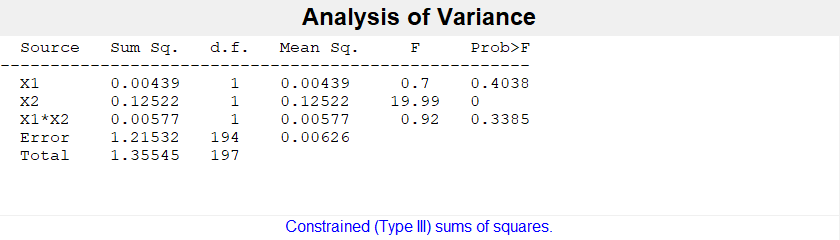

Current plot held


a = 0

b = 0.1855

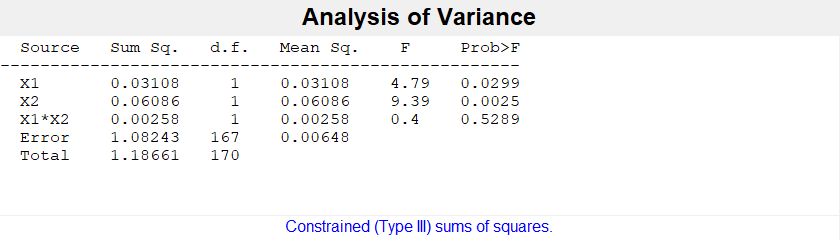


clear s
for i = 1:2
    curind = intersect(indfemOneFive_f, sigunsig{i});
    curind_c = intersect(indfemOneFive_cag_f, sigunsig{i});
    curind_s = intersect(indfemOneFive_str_f, sigunsig{i});
    
    us_p1 = unique(labels_pair(curind_c));
    us_p2 = unique(labels_pair(curind_s));
    us_p = [us_p1 ; us_p2];


    Distmat = IVdist_sess(sumbehavID2.^(1/3), curind, us_p, labels_pair, distmet);
  
    windistmat_sus = diag(Distmat);
    btwdistmat_sus = Distmat;
    btwdistmat_sus(find(eye(length(Distmat)))) = nan;

    lpsus = length(us_p1);
    lpsusS = length(us_p2);
    win_cag_sus{i} = windistmat_sus(1:lpsus);
    btw_cag_sus{i} = reshape(btwdistmat_sus(1:lpsus, 1:lpsus), 1,[]);
    win_str_sus{i} = windistmat_sus(lpsus+(1:lpsusS)); 
    btw_str_sus{i} = reshape(btwdistmat_sus(lpsus+(1:lpsusS),lpsus+(1:lpsusS)), 1,[]);

figure(f)
subplot(1,2,i)
hold

%  s{i,1} = swarmchart(ones(length(win_cag_sus{i}),1), win_cag_sus{i}, 10, 'k');
%  
%  s{i,2} = swarmchart(2*ones(length(btw_cag_sus{i}),1), btw_cag_sus{i}, 10, 'k');
%  
%  s{i,3} = swarmchart(3*ones(length(win_str_sus{i}),1), win_str_sus{i}, 10, 'r') ;
%  s{i,4} = swarmchart(4*ones(length(btw_str_sus{i}),1), btw_str_sus{i}, 10, 'r');

 s{i,1} = swarmchart(ones(length(win_cag_sus{i}),1), win_cag_sus{i}, 10, 'CData', colorcodes_f(2,:));
%  
%  s{i,2} = swarmchart(2*ones(length(btw_cag_sus{i}),1), btw_cag_sus{i}, 10, 'k');
%  
  s{i,2} = swarmchart(2*ones(length(win_str_sus{i}),1), win_str_sus{i}, 10, 'CData', colorcodes_f(1,:)) ;
%  s{i,4} = swarmchart(4*ones(length(btw_str_sus{i}),1), btw_str_sus{i}, 10, 'r');

 
 set(get(s{i,1}, 'Parent'), 'XLim', [.5 2.5]);
 
 for j = 1:2 % change to 4 when including hte "between"
     set(s{i,j}, 'XJitterWidth', .3);
 end
 
    anovacell{1} = [win_cag_sus{i} ; btw_cag_sus{i}' ; win_str_sus{i} ; btw_str_sus{i}'];
    anovacell{2} = [ones(length(win_cag_sus{i}),1) ; ones(length(btw_cag_sus{i}),1) ; 2*ones(length(win_str_sus{i}),1) ; 2*ones(length(btw_str_sus{i}),1)];
    anovacell{3} = [ones(length(win_cag_sus{i}),1) ; 2*ones(length(btw_cag_sus{i}),1) ; ones(length(win_str_sus{i}),1) ; 2*ones(length(btw_str_sus{i}),1)];
    
    [a b] = ttest2(win_cag_sus{i}, win_str_sus{i})

 
     [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');
    P_SUS(:,i) = P;
    T_SUS{i} = T;
    
    [~, pvBSUS(i)] = vartest2(btw_cag_sus{i}, btw_str_sus{i});
    sBSUS(i,:) = [nanstd(btw_cag_sus{i}) nanstd(btw_str_sus{i})];
%f-test of uneven variances: within
    [~, pvWSUS(i)] = vartest2(win_cag_sus{i}, win_str_sus{i});
    [~, pmBSUS(i), ~, tstat{i}] = ttest2(btw_cag_sus{i}, btw_str_sus{i});
    [~, pmWSUS(i), ~, tstat{i}] = ttest2(win_cag_sus{i}, win_str_sus{i});

    ylim(i,:) = get(get(s{i,1},'Parent'), 'YLim');
    
  box off
end

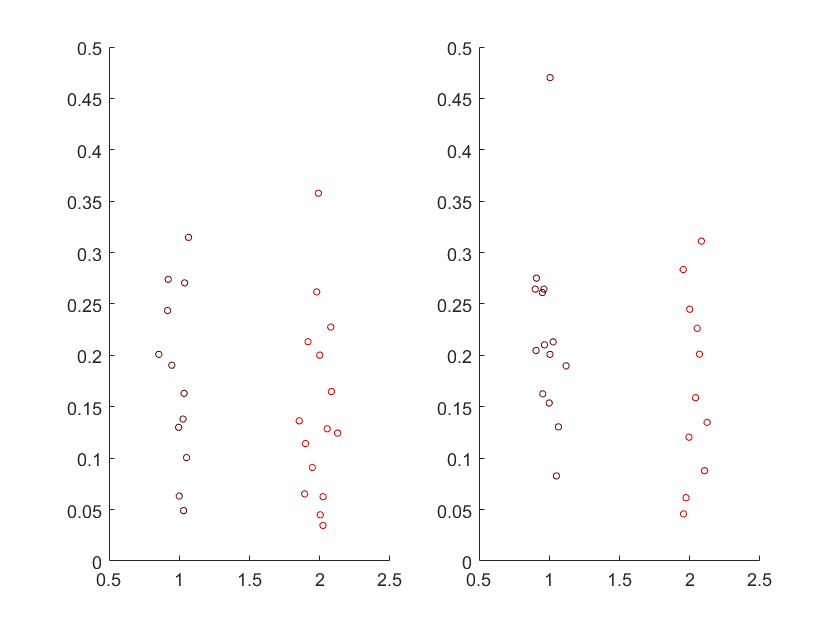

minylim = min(min(ylim));
maxylim = max(max(ylim));
for i = 1:2
    set(get(s{i,1}, 'Parent'), 'YLim', [minylim maxylim]);    
end

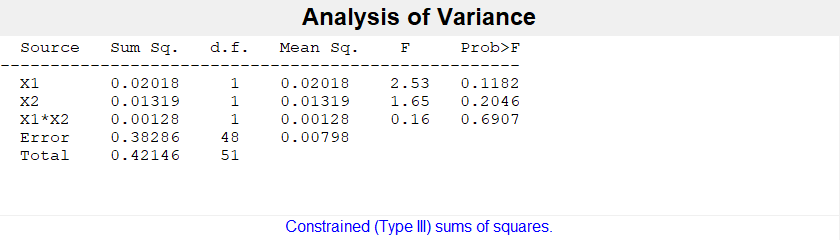

    anovacell{1} = [win_cag_sus{1} ; win_cag_sus{2} ; win_str_sus{1} ; win_str_sus{2}];
    anovacell{2} = [ones(length(win_cag_sus{1}),1) ; ones(length(win_cag_sus{2}),1) ; 2*ones(length(win_str_sus{1}),1) ; 2*ones(length(win_str_sus{2}),1)];
    anovacell{3} = [ones(length(win_cag_sus{1}),1) ; 2*ones(length(win_cag_sus{2}),1) ; ones(length(win_str_sus{1}),1) ; 2*ones(length(win_str_sus{2}),1)];
    [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

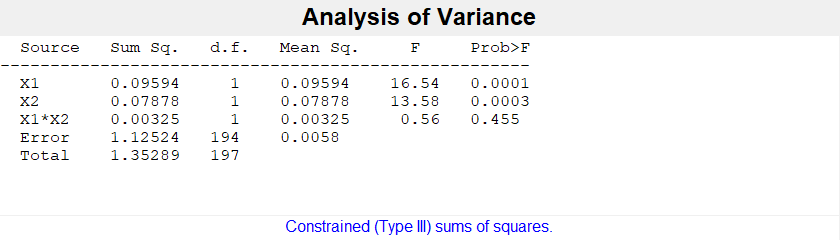

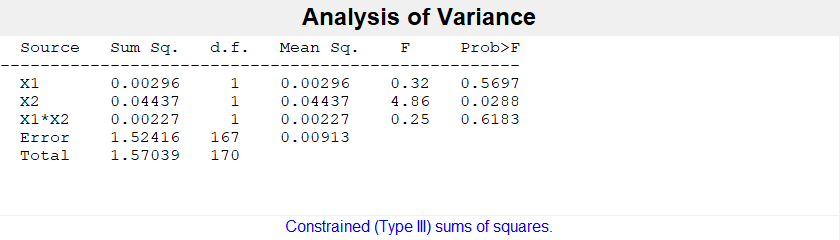

 %This code was moved to part 0 (Setup)
%
% sigdyads = find(ismember(rdb_rr.deguA, degutable(indsig,1)) | ismember(rdb_rr.deguB, degutable(indsig,1)));
% usig = unique(sigdyads);
% nonsigdyads = find(~ismember(1:length(rdb_rr.deguA), sigdyads));
% unsig = unique(nonsigdyads);
% 
% 
% indsig_f = find(ismember(fem_ind(FiA), sigdyads));
% indnonsig_f = find(ismember(fem_ind(FiA), nonsigdyads));

    distmet = 'neuclidean';
sigunsig = {sigdyads, nonsigdyads};

for i = 1:2
    curind = intersect(indfemOneFive_f, sigunsig{i});
    curind_c = intersect(indfemOneFive_cag_f, sigunsig{i});
    curind_s = intersect(indfemOneFive_str_f, sigunsig{i});
    
    us_p1 = unique(labels_pair(curind_c));
    us_p2 = unique(labels_pair(curind_s));
    us_p = [us_p1 ; us_p2];


    Distmat = IVdist_sess(sumbehavID2.^(1/3), curind, us_p, labels_pair, distmet);
  
    windistmat_sus = diag(Distmat);
    btwdistmat_sus = Distmat;
    btwdistmat_sus(find(eye(length(Distmat)))) = nan;

    lpsus = length(us_p1);
    lpsusS = length(us_p2);
    win_cag_sus{i} = windistmat_sus(1:lpsus);
    btw_cag_sus{i} = reshape(btwdistmat_sus(1:lpsus, 1:lpsus), 1,[]);
    win_str_sus{i} = windistmat_sus(lpsus+(1:lpsusS)); 
    btw_str_sus{i} = reshape(btwdistmat_sus(lpsus+(1:lpsusS),lpsus+(1:lpsusS)), 1,[]);



 
 for j = 1:4
     set(s{j}, 'XJitterWidth', .3);
 end
 
    anovacell{1} = [win_cag_sus{i} ; btw_cag_sus{i}' ; win_str_sus{i} ; btw_str_sus{i}'];
    anovacell{2} = [ones(length(win_cag_sus{i}),1) ; ones(length(btw_cag_sus{i}),1) ; 2*ones(length(win_str_sus{i}),1) ; 2*ones(length(btw_str_sus{i}),1)];
    anovacell{3} = [ones(length(win_cag_sus{i}),1) ; 2*ones(length(btw_cag_sus{i}),1) ; ones(length(win_str_sus{i}),1) ; 2*ones(length(btw_str_sus{i}),1)];
    
 
     [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');
    P_SUS(:,i) = P;
    T_SUS{i} = T;
    
    [~, pvBSUS(i)] = vartest2(btw_cag_sus{i}, btw_str_sus{i});
    sBSUS(i,:) = [nanstd(btw_cag_sus{i}) nanstd(btw_str_sus{i})];
%f-test of uneven variances: within
    [~, pvWSUS(i)] = vartest2(win_cag_sus{i}, win_str_sus{i});
    [~, pmBSUS(i), ~, tstat{i}] = ttest2(btw_cag_sus{i}, btw_str_sus{i});
    [~, pmWSUS(i), ~, tstat{i}] = ttest2(win_cag_sus{i}, win_str_sus{i});

    
  box off
end

### Compare distances over days

Distance over days: cosine

distmet = 'cosine'; 


% Female distances 
indfemall = intersect(find(rdb_rr.strangercode <= 2), fem_ind);
  indfemallcag = intersect(find(rdb_rr.strangercode == 0), fem_ind);
  indfemallstr = intersect(find(rdb_rr.strangercode == 1), fem_ind);
  indfemallnst = intersect(find(rdb_rr.strangercode == 2), fem_ind);
  
  u_p1_f = unique(labels_pair(indfemallcag));
  u_p2_f = unique(labels_pair(indfemallstr));
  u_p3_f = unique(labels_pair(indfemallnst));
  u_p_f = [u_p1_f ; u_p2_f ; u_p3_f];
  
  lp_f = length(u_p1_f);


% Male distances 
exp_pair = rdb_rr.exposurenum;
IVdistall_f = IVdist_sess_all(sumbehavID2.^(1/3), indfemall, u_p_f, labels_pair, exp_pair, distmet);


indmalall = intersect(find(rdb_rr.strangercode <= 2), mal_ind);
  indmalallcag = intersect(find(rdb_rr.strangercode == 0), mal_ind);
  indmalallstr = intersect(find(rdb_rr.strangercode == 1), mal_ind);
  indmalallnst = intersect(find(rdb_rr.strangercode == 2), mal_ind);
  
  u_p1_m = unique(labels_pair(indmalallcag));
  u_p2_m = unique(labels_pair(indmalallstr));
  u_p3_m = unique(labels_pair(indmalallnst));
  u_p_m = [u_p1_m ; u_p2_m ; u_p3_m];
  
  lp_m = length(u_p1_m);

exp_pair = rdb_rr.exposurenum;
IVdistall_m = IVdist_sess_all(sumbehavID2.^(1/3), indmalall, u_p_m, labels_pair, exp_pair, distmet);




% Distances within and between dyads

meanDistXDay_f = nan(length(u_p_f),9);
meandist_subseq_f = nan(length(u_p_f), 8);

meanDistXDay_m = nan(length(u_p_m),9);
meandist_subseq_m = nan(length(u_p_m), 8);

for i = 1:length(u_p_f)
    curmat = IVdistall_f{i,i};
    for j = 1:length(curmat)
        if length(curmat) < 5
            meanDistXDay_f(i, j) = nanmean(curmat(j,1:2));
         %   medianDistXDay_f(i, j) = nanmedian(curmat(j,1:2));
        else
           meanDistXDay_f(i, j) = nanmean(curmat(j,1:5));
         %  medianDistXDay_f(i, j) = nanmedian(curmat(j,1:5));
        end
    end
  %      if length(curmat) >= 5 % has to be the cagemate or ostranger (not new stranger). So, 5 or more sessions
           dcm = diag(curmat,1); %within
           
           meandist_subseq_f(i,1:length(dcm)) = dcm;  %added for examination of C-C vs. C-S    
           %     end
    
     
           
end

for i = 1:length(u_p_m)
    curmat = IVdistall_m{i,i};
    for j = 1:length(curmat)
        if length(curmat) < 5
            meanDistXDay_m(i, j) = nanmean(curmat(j,1:2));
         %   medianDistXDay_f(i, j) = nanmedian(curmat(j,1:2));
        else
           meanDistXDay_m(i, j) = nanmean(curmat(j,1:5));
         %  medianDistXDay_f(i, j) = nanmedian(curmat(j,1:5));
        end
    end
%        if length(curmat) >= 5 % has to be the cagemate or ostranger (not new stranger). So, 5 or more sessions
           dcm = diag(curmat,1);
               meandist_subseq_m(i,1:length(dcm)) = dcm; %added for examination of C-C vs. C-S    
 %       end
end



figure
subplot(1,15,1:9)
e1 = errorbar(1:9, nanmean(meanDistXDay_f(1:lp_f, :)), nanstd(meanDistXDay_f(1:lp_f,:))/sqrt(lp_f-1), 'Color', colorcodes_fem(2,:));
hold 

Current plot held


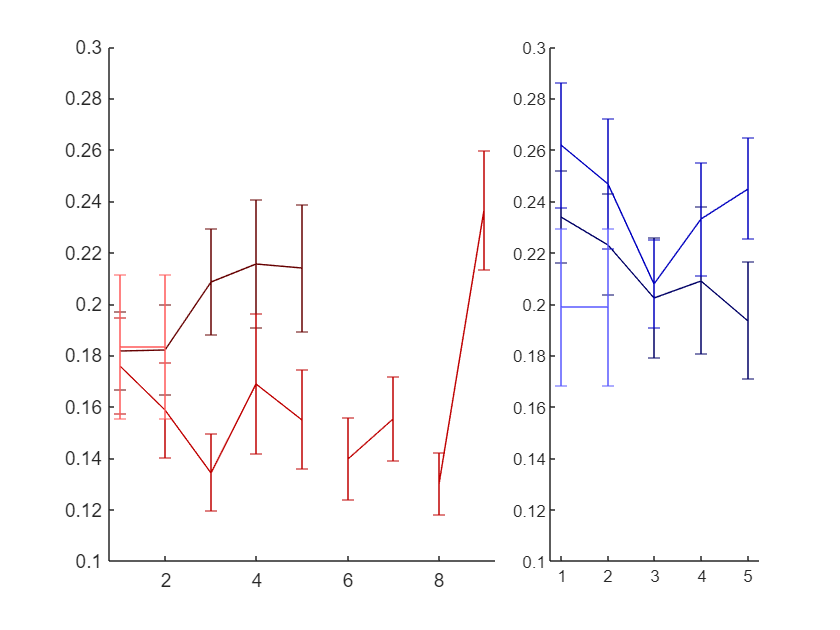

errorbar(1:5, nanmean(meanDistXDay_f(lp_f+(1:lp_f), 1:5)), nanstd(meanDistXDay_f(lp_f+(1:lp_f),1:5))/sqrt(lp_f-1), 'Color', colorcodes_fem(1,:));
errorbar(6:7, nanmean(meanDistXDay_f(lp_f+(1:lp_f), 6:7)), nanstd(meanDistXDay_f(lp_f+(1:lp_f),6:7))/sqrt(length(~isnan(meanDistXDay_f(lp_f+(1:lp_f),7)))), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(meanDistXDay_f(lp_f+(1:lp_f), 8:9)), nanstd(meanDistXDay_f(lp_f+(1:lp_f),8:9))/sqrt(length(~isnan(meanDistXDay_f(lp_f+(1:lp_f),9)))), 'Color', colorcodes_fem(1,:));
errorbar(1:2, nanmean(meanDistXDay_f(lp_f*2+(1:lp_f), 1:2)), nanstd(meanDistXDay_f(lp_f*2+(1:lp_f),1:2))/sqrt(length(nstrangers_f)-1), 'Color', colorcodes_fem(3,:));
box off
set(get(e1, 'Parent'), 'XLim', [.75 9.25])

    
%figure
subplot(1,15,11:15)
e2 = errorbar(1:9, nanmean(meanDistXDay_m(1:lp_m, :)), nanstd(meanDistXDay_f(1:lp_m,:))/sqrt(lp_m-1), 'Color', colorcodes_mal(2,:));
hold on
errorbar(1:5, nanmean(meanDistXDay_m(lp_m+(1:lp_m), 1:5)), nanstd(meanDistXDay_m(lp_m+(1:lp_m),1:5))/sqrt(lp_m-1), 'Color', colorcodes_mal(1,:));
errorbar(6:7, nanmean(meanDistXDay_m(lp_m+(1:lp_m), 6:7)), nanstd(meanDistXDay_m(lp_m+(1:lp_m),6:7))/sqrt(length(~isnan(meanDistXDay_m(lp_m+(1:lp_m),7)))), 'Color', colorcodes_mal(1,:));
errorbar(8:9, nanmean(meanDistXDay_m(lp_m+(1:lp_m), 8:9)), nanstd(meanDistXDay_m(lp_m+(1:lp_m),8:9))/sqrt(length(~isnan(meanDistXDay_m(lp_m+(1:lp_m),9)))), 'Color', colorcodes_mal(1,:));
errorbar(1:2, nanmean(meanDistXDay_m(lp_m*2+(1:lp_m), 1:2)), nanstd(meanDistXDay_m(lp_m*2+(1:lp_m),1:2))/sqrt(length(nstrangers_m)-1), 'Color', colorcodes_mal(3,:));
box off
set(get(e2, 'Parent'), 'XLim', [.75 5.25])

ylims_1 = get(get(e1, 'Parent'), 'YLim');
ylims_2 = get(get(e2, 'Parent'), 'YLim');
ylimboth(1) = min([ylims_1(1) ylims_2(1)]);
ylimboth(2) = max([ylims_1(2) ylims_2(2)]);

set(get(e1, 'Parent'), 'YLim', ylimboth)
set(get(e2, 'Parent'), 'YLim', ylimboth)

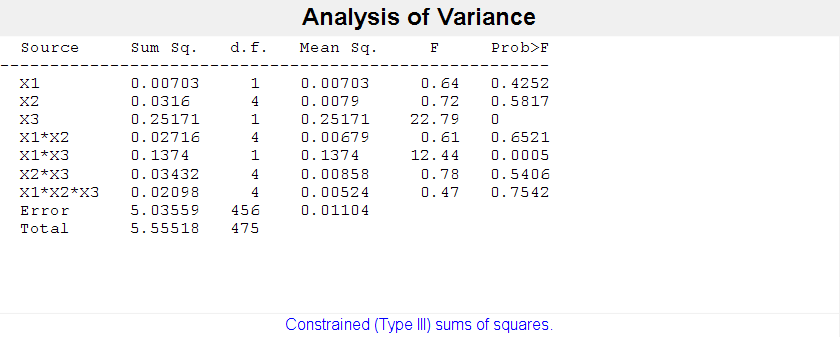


    anovacell{1} = reshape([meanDistXDay_f(1:(2*lp_f),1:5) ; meanDistXDay_m(1:(2*lp_m),1:5)], [],1);
    anovacell{2} = reshape([ones(lp_f,5) ; 2*ones(lp_f,5) ; ones(lp_m,5) ; 2*ones(lp_m,5)], [],1);
    anovacell{3} = reshape(repmat(1:5, 2*lp_f+2*lp_m, 1), [], 1);
    anovacell{4} = reshape([ones(2*lp_f,5) ; 2*ones(2*lp_m,5)], [], 1);
 
     [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:4), 'model', 'full');

     mdxd_t = [meanDistXDay_f(1:lp_f, 1:5) ; meanDistXDay_f((lp_f+1):(2*lp_f), 1:5)];
    mdxd_sc = [zeros(lp_f, 1); ones(lp_f,1)];
%    mdxd_fm = [zeros(2*lp_f,1) ; ones(2*lp_m,1)];
         
     tbl = simple_mixed_anova(mdxd_t, mdxd_sc, {'exposureday'}, {'cagstr'}) % between_factors, {'ex

tbl = 6×8 table
                                SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                               ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                  7.9886      1       7.9886    196.86    2.0158e-18    2.0158e-18    2.0158e-18    2.0158e-18
    cagstr                     0.087672      1     0.087672    2.1605       0.14826       0.14826       0.14826       0.14826
    Error                        1.9073     47      0.04058                                                                  
    (Intercept):exposu

     
         mdxd_t = [meanDistXDay_m(1:lp_m, 1:5) ; meanDistXDay_m((lp_m+1):(2*lp_m), 1:5)];
    mdxd_sc = [zeros(lp_m, 1); ones(lp_m,1)];
%    mdxd_fm = [zeros(2*lp_f,1) ; ones(2*lp_m,1)];
         
     tbl = simple_mixed_anova(mdxd_t, [mdxd_sc], {'exposureday'}, {'cagstr'}) % between_factors, {'ex

tbl = 6×8 table
                                SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                               ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                  10.533      1       10.533     294.32    2.5697e-20    2.5697e-20    2.5697e-20    2.5697e-20
    cagstr                     0.066241      1     0.066241     1.8509       0.18111       0.18111       0.18111       0.18111
    Error                        1.4673     41     0.035788                                                                   
    (Intercept):e

     
     
     
     
     mdxd_t = [meanDistXDay_f(1:lp_f, 1:5) ; meanDistXDay_f((lp_f+1):(2*lp_f), 1:5) ; meanDistXDay_m(1:lp_m, 1:5) ; meanDistXDay_m((lp_m+1):(2*lp_m), 1:5)];
    mdxd_sc = [zeros(lp_f, 1); ones(lp_f,1) ; zeros(lp_m, 1); ones(lp_m,1)];
    mdxd_fm = [zeros(2*lp_f,1) ; ones(2*lp_m,1)];
         
     tbl = simple_mixed_anova(mdxd_t, [mdxd_sc mdxd_fm], {'exposureday'}, {'cagstr', 'sex'}) % between_factors, {'exposures', 'cagVstr'})

tbl = 10×8 table
                                 SumSq       DF       MeanSq          F          pValue       pValueGG      pValueHF      pValueLB 
                               __________    ___    __________    _________    __________    __________    __________    __________

    (Intercept)                    18.498      1        18.498       482.37    1.7799e-37    1.7799e-37    1.7799e-37    1.7799e-37
    cagstr                     0.00021273      1    0.00021273    0.0055473        0.9408        0.9408        0.9408        0.9408
    sex                           0.19044      1       0.19044       4.9662      0.028396      0.028396      0.028396      0.028396

     


% figure
% e1 = errorbar(1:8, nanmean(meandist_subseq_f(1:lp_f, :)), nanstd(meandist_subseq_f(1:lp_f,:))/sqrt(lp_f-1), 'Color', colorcodes_fem(2,:));
% hold 
% errorbar(1:4, nanmean(meandist_subseq_f(lp_f+(1:lp_f), 1:4)), nanstd(meandist_subseq_f(lp_f+(1:lp_f),1:4))/sqrt(lp_f-1), 'Color', colorcodes_fem(1,:));
% errorbar(6, nanmean(meandist_subseq_f(lp_f+(1:lp_f), 6)), nanstd(meandist_subseq_f(lp_f+(1:lp_f),6))/sqrt(length(~isnan(meandist_subseq_f(lp_f+(1:lp_f),7)))), 'Color', colorcodes_fem(1,:));
% errorbar(8, nanmean(meandist_subseq_f(lp_f+(1:lp_f), 8)), nanstd(meandist_subseq_f(lp_f+(1:lp_f),8))/sqrt(length(~isnan(meandist_subseq_f(lp_f+(1:lp_f),9)))), 'Color', colorcodes_fem(1,:));
% errorbar(1, nanmean(meandist_subseq_f(lp_f*2+(1:lp_f), 1)), nanstd(meandist_subseq_f(lp_f*2+(1:lp_f),1:2))/sqrt(length(nstrangers_f)-1), 'Color', colorcodes_fem(3,:));
% box off
% set(get(e1, 'Parent'), 'XLim', [.75 9.25])
% 
% %figure
% e2 = errorbar(1:8, nanmean(meandist_subseq_m(1:lp_m, :)), nanstd(meanDistXDay_f(1:lp_m,:))/sqrt(lp_m-1), 'Color', colorcodes_mal(2,:));
% hold on
% errorbar(1:4, nanmean(meandist_subseq_m(lp_m+(1:lp_m), 1:5)), nanstd(meandist_subseq_m(lp_m+(1:lp_m),1:5))/sqrt(lp_m-1), 'Color', colorcodes_mal(1,:));
% %errorbar(6:7, nanmean(meandist_subseq_m(lp_m+(1:lp_m), 6:7)), nanstd(meandist_subseq_m(lp_m+(1:lp_m),6:7))/sqrt(length(~isnan(meandist_subseq_m(lp_m+(1:lp_m),7)))), 'Color', colorcodes_mal(1,:));
% %errorbar(8:9, nanmean(meandist_subseq_m(lp_m+(1:lp_m), 8:9)), nanstd(meandist_subseq_m(lp_m+(1:lp_m),8:9))/sqrt(length(~isnan(meandist_subseq_m(lp_m+(1:lp_m),9)))), 'Color', colorcodes_mal(1,:));
% errorbar(1, nanmean(meandist_subseq_m(lp_m*2+(1:lp_m), 1:2)), nanstd(meandist_subseq_m(lp_m*2+(1:lp_m),1))/sqrt(length(nstrangers_m)-1), 'Color', colorcodes_mal(3,:));
% box off
% set(get(e2, 'Parent'), 'XLim', [.75 9.25])

#### Very messy comparison of C-C vs. C-S (and S-S vs. S-C) sequences (not included)     

meandistCag and meandistStr need to be generated--check previous versions

%      strorder_d = Rdb_csOrder(rdb_rr); %here's the first index: the deguOrder
%     o_sc = strorder_d(:,2:11); %all 10 sessions
%      
%      d_o = diff(o_sc')';
%      %d_o_sc = d_o(:,2:10); % only sessions 2 through 10
% 
% 
% dlist = strorder_d(:,1);
% 
%    [u_p1, ia_p1, ib_p1] = unique(labels_pair(indfemOneFive_cag_f));
%    [u_p2, ia_p2, ib_p2] = unique(labels_pair(indfemOneFive_str_f));
%    
% %   comb_degunum = Rdb_strfirst(rdb_rr, rdb_rr.deguA(indfemOneFive));
%    
%    comb_ia = [ia_p1 ; ia_p2];
% 
%    degunums_comb = [rdb_rr.deguA(indfemOneFive_cag_f(ia_p1)) ; rdb_rr.deguB(indfemOneFive_cag_f(ia_p1))]; %here's the second index: the deguCag
%    degunums_somb = [rdb_rr.deguA(indfemOneFive_str_f(ia_p2)) ; rdb_rr.deguB(indfemOneFive_str_f(ia_p2))]; %a third index: the deguSTR
% 
%    simscore_ccss = nan(52,4);
%    meandist_row = nan(52,10);
% 
%    for i = 1:length(degunums_comb)
%        tempind = find(ismember(dlist(:,1), degunums_comb(i))); %mapping from deguOrder to deguCag
%        osc_row = o_sc(tempind, :); %mapped to deguCag
%                             
%        c_ind = find(~osc_row);       
%        s_ind = find(osc_row); 
%        
%        cdeguind = i;  % a fourth index: the meandistCag. Should be the same as deguCag for the first 1 through lp
%        if cdeguind > lp_f
%            cdeguind = i-lp_f;
%        end
%        sdeguind = find(degunums_somb == degunums_comb(i)); %a fifth index: the meandistStr. different from meandistCag
%        
%        if sdeguind <= lp_f
%            sdeguind = sdeguind + lp_f;
%        end
%        
%        meandist_row(i, c_ind(2:end)) = meandist_subseq(cdeguind,:); %the meandistCag will go on deguCag
%        meandist_row(i, s_ind(2:end)) = meandist_subseq(sdeguind,:); %set the meandistStr
%        
%        
%        dosc_row = d_o(tempind, :); %maped to deguCag
%        
%        for j = 1:4
%            switch j
%                case 1
%                    tind = find(osc_row(2:end) == 0 & dosc_row(1:end) == 0); %cag-cag
%                case 2
%                    tind = find(osc_row(2:end) == 0 & dosc_row(1:end) == -1); %str-cag
%                case 3
%                    tind = find(osc_row(2:end) == 1 & dosc_row(1:end) == 0); %str-str
%                case 4
%                    tind = find(osc_row(2:end) == 1 & dosc_row(1:end) == 1); %cag-str
%            end                      
%            simscore_ccss(i,j) = nanmean(meandist_row(i,tind+1));     
%        end
%        
%    end
%    
%    
%    % We now have a matrix of individual degu data that's in the order of degunums_comb --- NOT in a
%    % meaningful order for stranger dyads 
%    
%    %now for each, find 4 types of sessions
%    
%    figure
%    b = errorbar(1:2, nanmean(simscore_ccss(:,1:2)), nanstd(simscore_ccss(:,1:2))/sqrt(length(simscore_ccss)), 'b');
%    hold
%    b = errorbar(3:4, nanmean(simscore_ccss(:,3:4)), nanstd(simscore_ccss(:,3:4))/sqrt(length(simscore_ccss)), 'r');
%    set(get(b, 'Parent'), 'XLim', [.75 4.25]);
%    box off
%    
%        anovacell{1} = reshape([simscore_ccss(:,1:2) ; simscore_ccss(:,3:4)], [],1);
%     anovacell{2} = reshape([ones(length(simscore_ccss),2) ; 2*ones(length(simscore_ccss),2)], [],1);
%  
%     anovacell{3} = reshape([ones(length(simscore_ccss)*2, 1) 2*ones(length(simscore_ccss)*2,1)], [],1);
%     
%     [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');
%     
%     tbl = simple_mixed_anova([simscore_ccss(:,1:2) ; simscore_ccss(:,3:4)], [ones(length(simscore_ccss),1) ; zeros(length(simscore_ccss), 1)], {'inter_v_non'}, {'cagstr'}) % between_factors, {'exposures', 'cagVstr'})
%      
    